# Examples of Distributions

You've previously learned about several common distributions you may encounter in your data. Now look at a few examples.

## Uniform Distribution

Uniform distributions occur when all possible outcomes are equally likely to occur. 

For example, consider a fair die. 

N = 12000;
rollVals = randi(6,[N,1]);
histogram(rollVals)
numObs = N/6

### Descriptive Statistics

uAvg = mean(rollVals)
uSd = std(rollVals)

## Normal Distribution

In a normal distribution, the likelihood of each outcome depends on the distance from the mean. Data is distributed symmetrically about the mean in a bell shape.

Approximately two thirds of the data falls within one standard deviation ($\sigma$) of the mean ($\mu$).

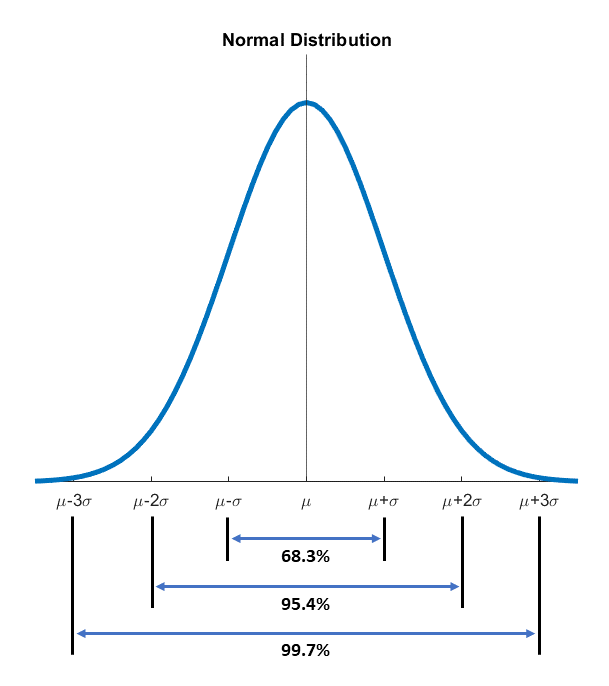

Load the flights data.

flights = importFlightsData("flightsFeb.csv");
% Use rmmissing to remove entries with data missing in the indicated variables
flights = rmmissing(flights,"DataVariables",["ACTUAL_ELAPSED_TIME","SCHEDULED_ELAPSED_TIME"]);
flights.DURATION_DIFF = flights.ACTUAL_ELAPSED_TIME-flights.SCHEDULED_ELAPSED_TIME;

histogram(flights.DURATION_DIFF,"BinWidth",2)
title("Elapsed Flight Time Difference (Actual - Scheduled)")
ylabel("Count (flights)")
xlabel("Difference (mins)")

### Descriptive Statistics

Compute the mean and standard deviation of DURATION_DIFF

nAvg = mean((flights.DURATION_DIFF))
nSd = std((flights.DURATION_DIFF))

Find the range of values within 1 standard deviation of the mean.

[nAvg-nSd nAvg+nSd]

% Add vertical lines indicating the bounds containing ~68% of the data
xline(nAvg+nSd);
xline(nAvg-nSd);

#### Kurtosis & Skewness

Use the `kurtosis` function to obtain a measure of how your distribution compares to a normal distribution, which has a kurtosis value of 3. A kurtosis value greater than 3 means the distribution is more outlier-prone than the normal distribution. Distributions that are less outlier-prone have a kurtosis value less than 3.

kt = kurtosis(flights.DURATION_DIFF)

Skewness is a measure of the asymmetry of the data around the sample mean. If the data is skewed left, skewness returns a negative value. If the data is skewed right, it returns a positive value. The normal distribution (or any perfectly symmetric distribution) has a skewness of zero. 

sk = skewness(flights.DURATION_DIFF)

## Box Plots

Box plots are commonly used to visualize distributions. The horizontal red line shows the median value. 

The box shows the extent of the interquartile range (IQR). The default whisker length extends to the last data point that is within 1.5 times the IQR box height.  

All data points outside the whiskers are considered outliers and are plotted individually. 

boxplot(flights.DURATION_DIFF)
title("Elapsed Flight Time Difference (Actual - Scheduled)")
ylabel("Difference (mins)")

The real power of box plots becomes apparent when you compare multiple datasets. For example, compare the duration difference from the 10 busiest airports.

% Determine the total number of flights originating from each airport.
topFlights = groupsummary(flights,"ORIGIN");
topAirports = topkrows(topFlights,10,"GroupCount");
topOrigins = topAirports.ORIGIN;

% Identify flights that were not canceled and not diverted.
idx = ismember(flights.ORIGIN,topOrigins) & flights.DIVERTED == 0 & flights.CANCELLED == 0;
boxplot(flights.DURATION_DIFF(idx),flights.ORIGIN(idx))
title("Elapsed Flight Time Difference (Actual - Scheduled) at 10 Busiest Airports")
ylabel("Difference (mins)")